# **sBAXTER**

# PLANEACIÓN DE TRAYECTORIAS

## **CINÉMATICA DIRECTA**

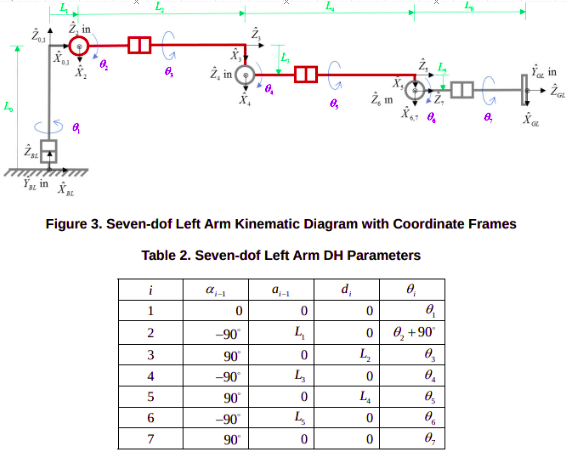

Ejemplo de la matriz de posicion en la cual los valores de X,Y ,Z ya son declarados por lo cual

se puede despejar los valores de th2 y th4

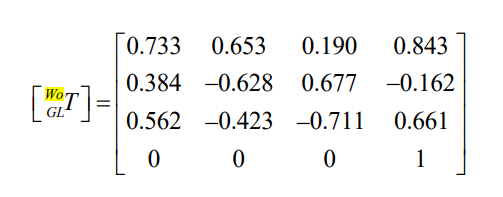


%%%en mm
l0=270.35
l1=69;
l2=364.35;
l3=364.35;
l4=374.29;
l5=10;
l6=368.30;
L=278;
h=64;
H=1104;
%%"en cinematica directa" primero se proporciona una matriz de
%%transfomracion desde wo(centro) hasta G(manipulador) la cual se debe
%%transformar a una matriz de transformacion de los grados de libertad

TwoGL=[0.733 0.653 0.190 0.843;0.384 -0.628 0.677 -0.162;0.562 0.423 0.711 0.661;0 0 0 1];
TwoBL=[cosd(45) sind(45) 0 L;-sind(45) cosd(45) 0 -h;0 0 1 H;0 0 0 1];
TwoBR=[-sind(45) cosd(45) 0 -L;-sind(45) -sind(45) 0 -h;0 0 1 H;0 0 0 1];
T6Gl=[1 0 0 0;0 1 0 0; 0 0 1 l6;0 0 0 1];
TBlO=[1 0 0 0;0 1 0 0; 0 0 1 l0;0 0 0 1];
TWoO=TwoBL*TBlO;
T0t6=inv(TWoO)*TwoGL*inv(T6Gl)


%%%%%%%%%%%%%%%%5tomando los valores de ejemplo de la matriz
x=T(1,4)
y=T(2,4)
Th1= atan2((y),(x)) %%% ya que tecnicamente seria atan2(Sin(th1),cos(th1)) segun el despeje, sin embargo
                  %%% solo nos estarian dando el valor de th1 sino solo los
                  %%% resutaldos de sin y cos o usando los valores de x y y
                  %%% que contienen th1%%%%%%%%%%%el resultado es en
                  %%% radianes
                
lh=sqrt(l2^2+l3^2);
E=2*lh*(l1-x/cosd(Th1));%% ni idea de que hago con x con esta variable
F=2*lh*z;
G=((x^2)/(cosd(Th1)^2))+l1^2+lh^2-l4^2+z^2-2*(l1*x/cosd(Th1));
%%%%%%%%%%%%del libro
Th2_1=2*arctan((-F+sqrt(E^2+F^2-G^2))/(G-E))
Th2_2=2*arctan((-F-sqrt(E^2+F^2-G^2))/(G-E))

Th3=0;

Th4_1=atan2((-z-lh*sin(Th2_1)),((x/cos(Th1)-l1-lh-lh*cos(th2_1))))
Th4_2=atan2((-z-lh*sin(Th2_2)),((x/cos(Th1)-l1-lh-lh*cos(th2_2))))
%%%%%%%%%%%%%%%%%%
Th6=atan2(sin(th6),cos(th6))

Th5=atan2(sin(th5),cos(th5))

Th7=atan2(sin(th7),cos(th7))